# Control of a racing car

The objective of this activity is to design some PI compensators to make the racing car lap the circuit in the quickest time possible. As this is a learning resource, some core assumptions need to be made to simplify the scenario and individuals can of course extend the modelling to enable more complex control algorithms, decision making and car models.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%          
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- The car model and track

- The desired steering angle

- The PI compensator for steering control

- The PI compensator for speed control

- The virtual laboratory

- Useful code

## 1 The car model and track

### 1.1 Car model

The car model is a relatively simple one taken from Gemini tools. It includes velocity dynamics and also some dynamics to take account of steering and slip. The relevant code is supplied in a subfunction at the end of this livescript.  Based on current information, the function outputs derivatives of core states which can then be used for model simulation by integrating these states.

%[dx, dy,dvy, dr,  dtheta] = cardynamics(vx, delta,vy, r, theta)
% vx is velocity and dx,dy are acceleration in the x,y, directions
% delta is steering and dtheta is the rate of turn
% vy, r and their derivatives dvy, dr are internal states
% theta is current heading angle

Given the purpose of this resource is educational rather than providing the most accurate modelling and simulation possible, the integration is done using a simple Euler approach. Indeed this is also consistent with the fact that real world scenarios will include numerous sources of uncertainty and parameter errors, so the accuracy of the model simulation is secondary when evaluating the control design choices. A sample time of 0.02 seconds is used which should be fast enough for typical car dynamics.

### 1.2. The track

The track is defined by using rates of curvature (***theta***) and ensuring a closed circuit.

[x,y,theta,direction,numberangles] = createtrack;

The track is defined by (x,y) co-ordinates at approximately 2 m separations. The variable ***direction*** indicates the current angle of the track in the (x,y) coordinate frame and ***numberangles*** gives the number of points required to define a complete lap.

Users can change the track by changing the definitions in the relevant sub-function within the app, but be careful to ensure that you have formed a closed-circuit.

**Remark**: The file adds a significant overlap (in essence continuation into lap 2) to the data to aid with location finding and code robustness.

### 1.3 Locating car position on the track

The most effective way is to use knowledge of the previous  car position to imply the current position and assuming the car is continuing on the correct direction;  this will only work well if the car is largely behaving sensibly. If it drifts of the track (see figure below) or steers poorly, such a mechanism could fail. Approaches to deal with off-track scenarios are beyond the remit of this resource.

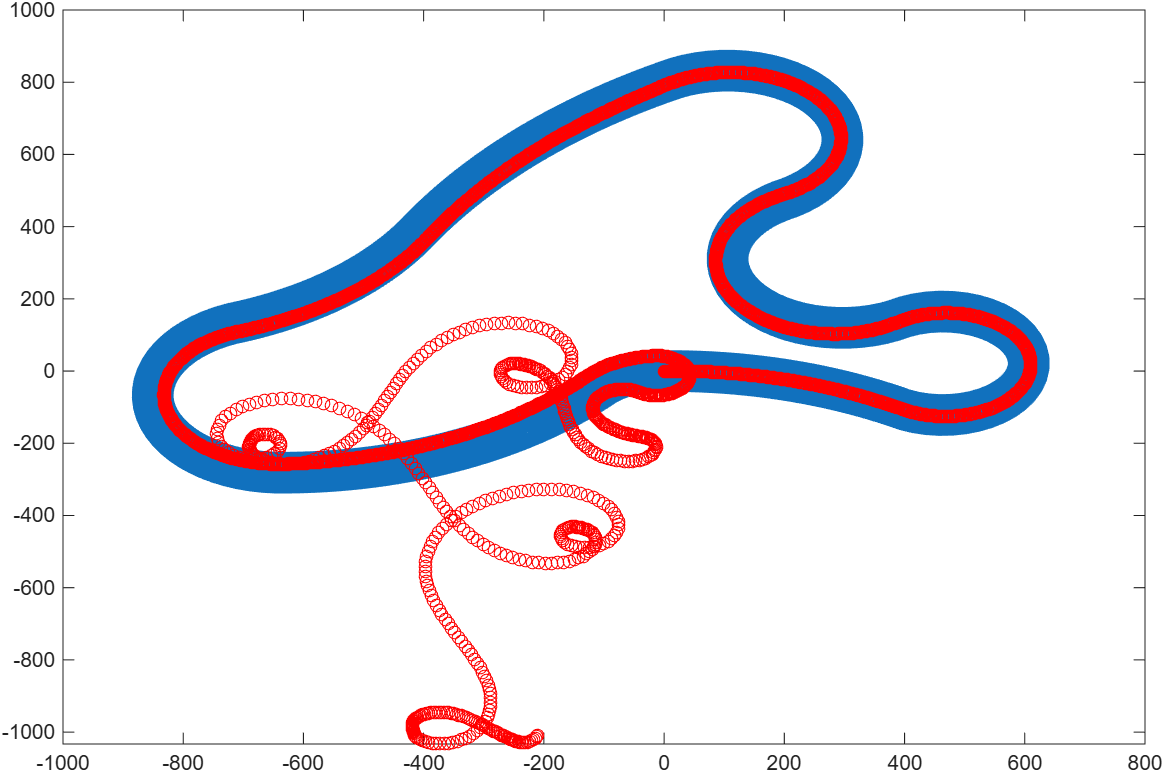

**Figure**: Illustration of car drifting of the track and becoming confused as to what to do next?

In essence the location uses a simple test.

- Assume you know that the car is currently between 2 points A and B.

- At the next sampled instant the car will either be between A and B or will have progressed to be between B and C, C being the next point on the track assuming correct flow.

- One simple needs to deduce whether the pairs (A,B) or (B,C) are more appropriate.

A subfunction ***nearesttrackpoints*** is used for this test.

**Remark**: Such a simple approach to selecting the nearest point must not be confused with target selection. The target is selected based on the track about 40m into the future with some mild filtering to reduce the discontinuities from the track being defined only at unique points.

### 1.4 Speed of the car

The simplest operation of the app assumes a constant throttle and thus a constant speed (after initial acceleration). However, due to the steepness of some of the bends, this speed is necessarily slow or the car will leave the  track. To utilise higher speeds on the straighter parts of the track, an additional speed control loop will need to be added. This speed control loop will need to be based on feedforward information, that is, linked to track position, and thus the desired speed would have to be manually assigned, and then a control loop added to achieve this desired speed. 

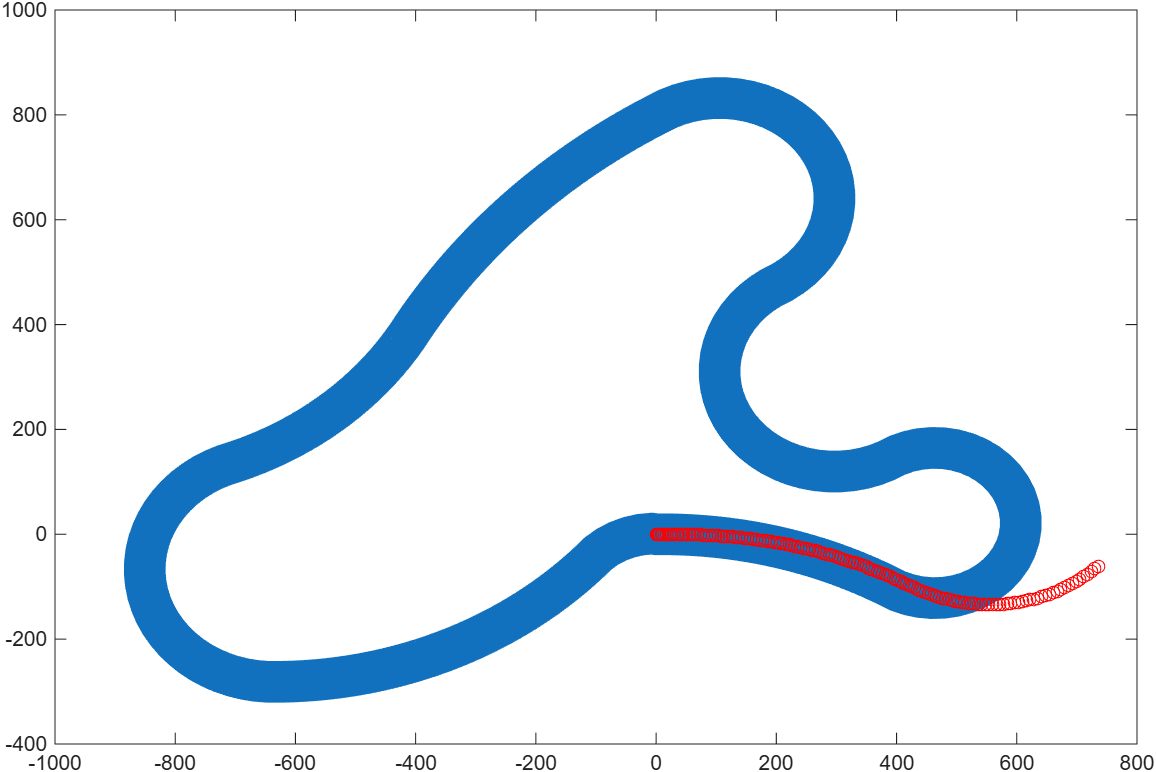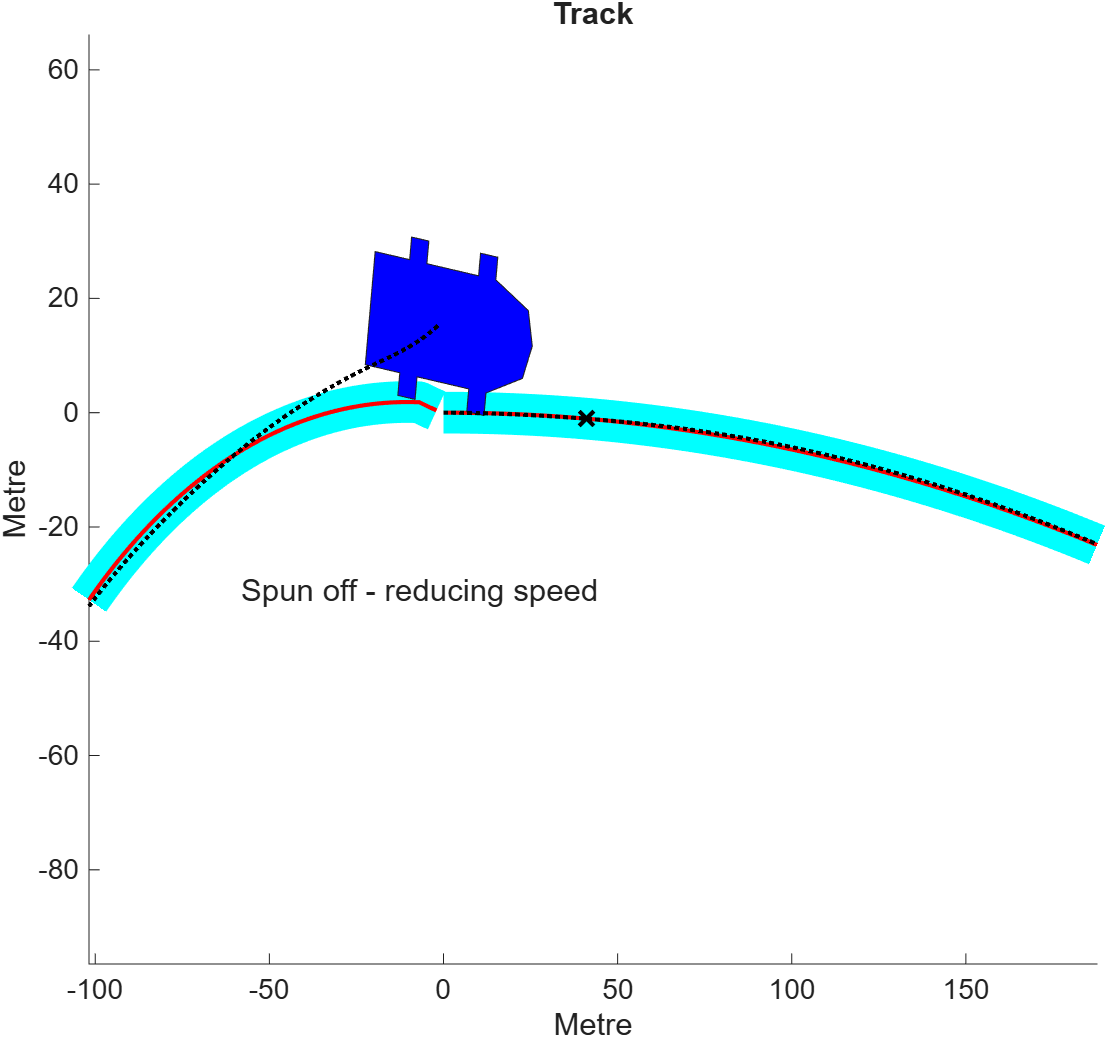

**Figure**: Illustration of going too fast such that car cannot mange a corner.

**Remark**: Currently the car model has no braking (a 3rd control action) and slows down solely due to friction and this will limit how fast it is wise to go.

## 2 The desired steering angle

The most important requirement for this activity is to control the steering of the car. This is a combination of determining a high level strategy alongside a control loop designed to implement this. The simplest strategy could for example simply steer towards the track centerline, but this begs the question, which part of the centerline as the nearest point could be behind ? Human drivers will also know that we also need to take account of future bends in the track and anticipate to some extent. How far ahead we look is linked to the car velocity, but typically 2-3 seconds is a minimum. It is also noted, that as the track is defined at 2m intervals, some smoothing will be needed to avoid undersirable bumps in the information/target.

For simiplicity the code currently bases the target on the track centreline 20m into the future.

### 2.1 Equation of a circle

A pure pursuit type of approach will form a circular arc from  the current position and direction to a future point on the track, and thus we need to match an appropriate circle with:

- Position and direction of car now ($\left.x,y,\theta \right)$

- Position and direction of track in the future ($\left.X,Y,\phi \right)$

The equation of a circle can be in various forms, for example


$${\left(x-a\right)}^2 +{\left(y-b\right)}^2 =r^2 ;\;\;\;x-a=r\;\cos \;\theta ,\;y-b=r\;\sin \;\theta$$


The gradient of a circle at any given point is given as

$\frac{\mathrm{dy}}{\mathrm{dx}}=-\frac{x-a}{y-b}$  where $\frac{\mathrm{dy}}{\mathrm{dx}}=-\frac{1}{\tan \;\theta }$

We need to merge this with the known data to find $a,b,r$.


$${\left(x-a\right)}^2 +{\left(y-b\right)}^2 =r^2 ;\;\;-\frac{y-b}{x-b}=\tan \;\theta$$



$${\left(X-a\right)}^2 +{\left(Y-b\right)}^2 =r^2 ;\;\;-\frac{Y-b}{X-a}=\tan \;\phi$$


Also, and perhaps fundamentally, this problem is **over-determined**. We can find a circle to match the two points and the initial gradient, but this may not match the gradient at the second point!

A slightly simpler but approximate approach (assuming small angles) is to consider the distance *D* between the two points and the directional difference and infer the radius (curvature or aggressiveness of steering) from the formula:


$$D=r\left(\phi -\theta \right);\;\;\;\;\;D=\sqrt{{\left(X-x\right)}^2 +{\left(Y-y\right)}^2 }$$


Ideally we wish to steer to correct the directional difference and also the positional difference! However, we can see that this is somewhat involved and perhaps beyond the remit of an introductory and simple approach. The severity of steering would inevitably be linked to the required change in direction and not just  the track coordinates and moreover would require a control strategy with two inputs/errors.

### 2.2 A simple approach to determining the target steering direction

We could simply choose the aggressiveness of the steering based on the angle between the current car direction and the nearest path to the target point (see Figure below).

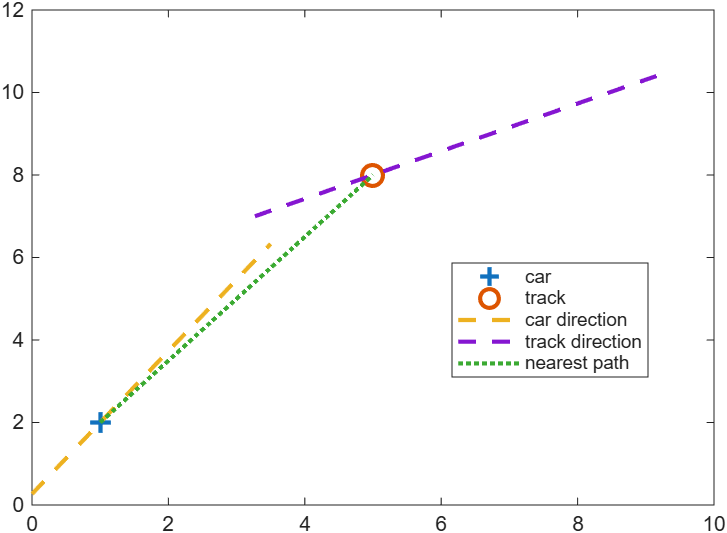

**Figure 2.1**: Illustration of car position and direction alongside a future track point.

So, treat the angle between the current direction and the nearest path as the error and choose a control law to minimise this error.

% desiredangle(k)=atan2((targety-y(k)),(targetx-x(k))); % angle of desired path

**WARNING**: The function ***atan*** is only unique to $\pi$ radians and sometimes the answer from an angle computation will jump by $\pi$ leading to unexpected and misleading consequences. Appropriate code based on history information is needed to ensure continuity.

### 2.3 Feedforward action

It is important to decide how far ahead is the target taken from? For example, at slow speeds one might only look 5-10m ahead whereas at faster speeds one may wish to look far further ahead (the horizon). This choice can have a significant impact on behaviour. For example (see figure 2.2), setting the target just 5-10m ahead while going fast will cause significant steering oscillations as the car needs large steering to correct relatively small offsets from the track centerline. 

The app allows the user to explore the impact of different horizon choices on the behaviour.

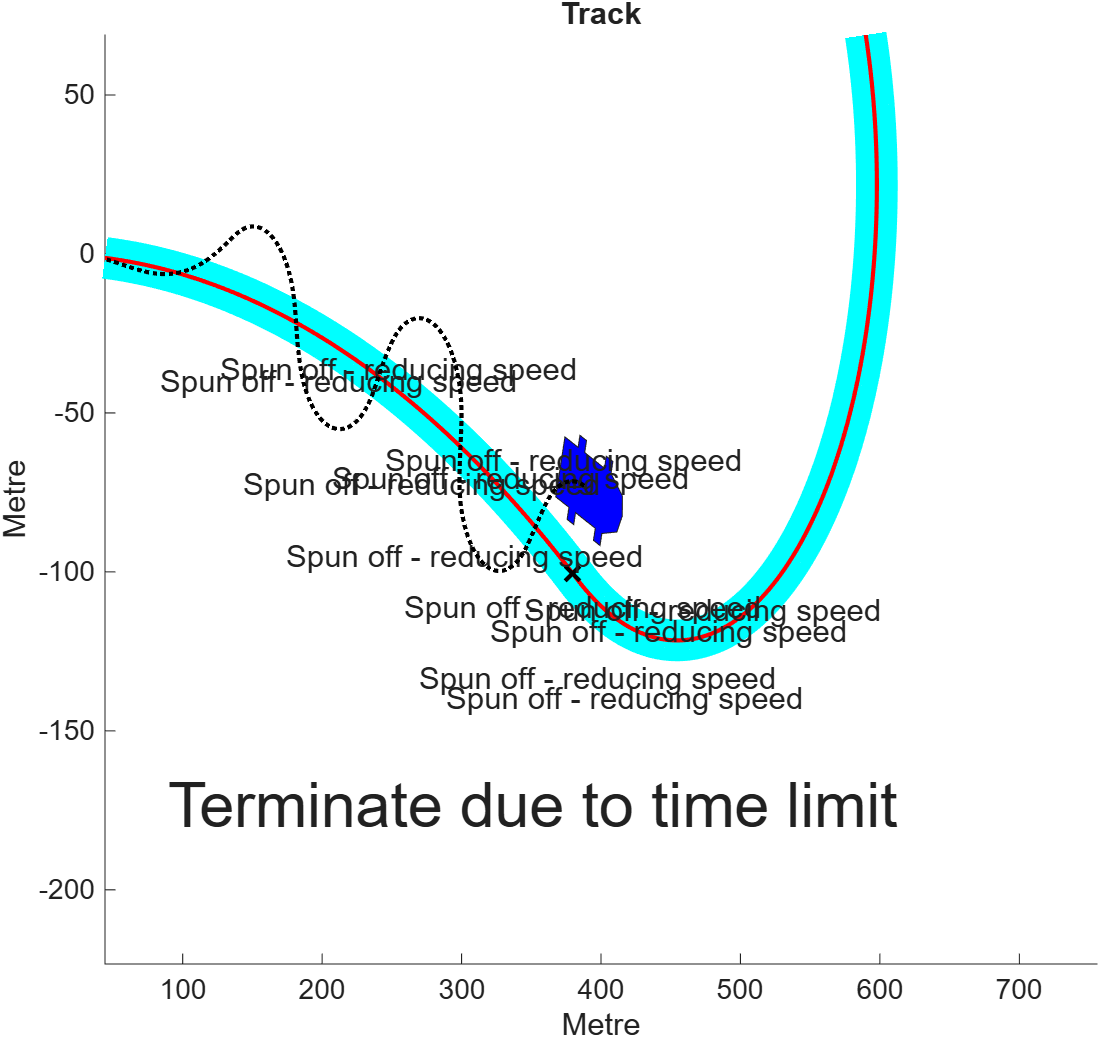

**Figure 2.2**: Illustration of car oscillation due to the target being too close to the car.

### 2.4 The need for filtering

As the information on the track profile and the car position are updated at set samples, there is inevitably some jumps in the errors and information will be evident in the final data. One can reduce these and create smoothing to some extent with a simple low pass filter, as shown here. However, this will add lag into the steering which will also lead to worse tracking around the track.


$$\mathrm{Filter}=\frac{1-b}{1-bz^{-1} };$$


% finaltarget(k)=0.1*desiredangle(k)+0.9*finaltarget(k-1);

This target direction will be used by the control law.

**Note**: The noisiness in the error information will be evident from the plots and this is solely due to the sampling of the track and the target updates being discrete. See Figure 2.3 below.  Ironically, this effect may be more evident at slower speeds.

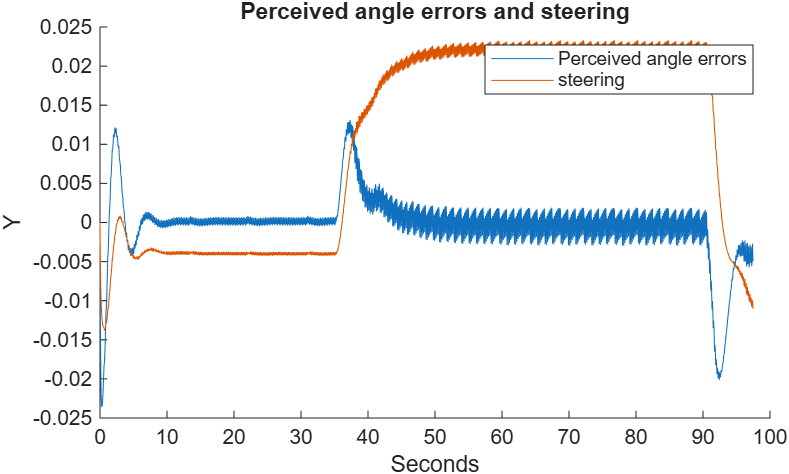

**Figure 2.3**: Illustration of the target update causing a noising error signal.

## 3 The PI compensator for steering control

For simplicity the resource currently uses a simple PI compensator for steering. 

### 3.1 The PI compensator

The desired steering direction target is summarised in sections 2.2-2.4 and the PI compensator uses this to produce a steering command $\delta$ to the car model. Note that $\theta$ is the current direction of the car.


$$\delta =\left(K_p +\frac{K_I }{s}\right)\left(\mathrm{Target}-\theta \right)$$


The user can select values for the proportional and integral terms using sliders.

The controller is implemented in a discrete form and the integral of the error is updated using a simple Euler method.

$\begin{array}{l}
e\left(k\right)=\left(\mathrm{Target}-\theta \right);\;\;\;\;\;\;\;\;E\left(k\right)=\sum_{k=0}^n e\left(k\right)\;T_s \\
\delta \left(k\right)=K_p e\left(k\right)+K_I E\left(k\right);
\end{array}$   where $T_s$ is the sample period.

### 3.2 Saturation and integral windup

In order to maintain some realism, the steering command is constrained to within lower and upper limits. In order to avoid integral windup, whenever saturation is detected, the integral term is frozen at the appropriate value so that the output of the PI compensator matches the current limit.

Ensure    $\underline{\delta} \le \delta \left(k\right)\le \bar{\delta}$       and then update $E\left(k\right)$ to enforce       $K_I E\left(k\right)=\delta \left(k\right)-K_p e\left(k\right)$

In a similar way, it would not be realistic for the steering to change to quickly so a rate constraint is applied.


$$\underline{R} \le \frac{\delta \left(k\right)-\delta \left(k\right)}{T_s }\le \bar{R}$$


### 3.3 Performance measures

To some extent the performance measures are for the user to define, but here some specific ones have been selected to allow comparison of different designs.

**Lap time**: Ultimately a racing car needs to lap as quickly as possible.

**Wear and tear and driver fatigue**:  The is linked to the aggressiveness of the steering so the 2nd measure is the 2-norm of the steering around a single lap.

**Fuel usage:** Faster speeds use more fuel.

**Lap complete**: Effective comparison of these measures requires the car to complete the lap so that the comparisons are using the same scenario. The final data stored under tab 2 is '1' for lap complete and '0' for lap incomplete.

**WARNING**: If the time is too short to complete a full lap (such as at low speeds), these measures will be based solely on the simulation provided and thus may not be easy to benchmark with each other.

## 4 The PI compensator for speed control

It is reasonable to assume that different speeds are needed for different corners to ensure the car optimises lap speed. For simplicity this app uses a simple ratio, that is, the speed targeted is proportional to the road curvature. However, the reader is reminded that the car has no braking, so speed can only be adjusted by changing the throttle.

### 4.1 PI control of speed

For this app, the user chooses the maximum throttle setting which would be selected down a straight piece of track. Lower throttle settings and speeds would be needed around the corners. The desired speed will be based on a 100m ahead forecast. The speed profile for this track is a selected as shown in Figure 4.1.

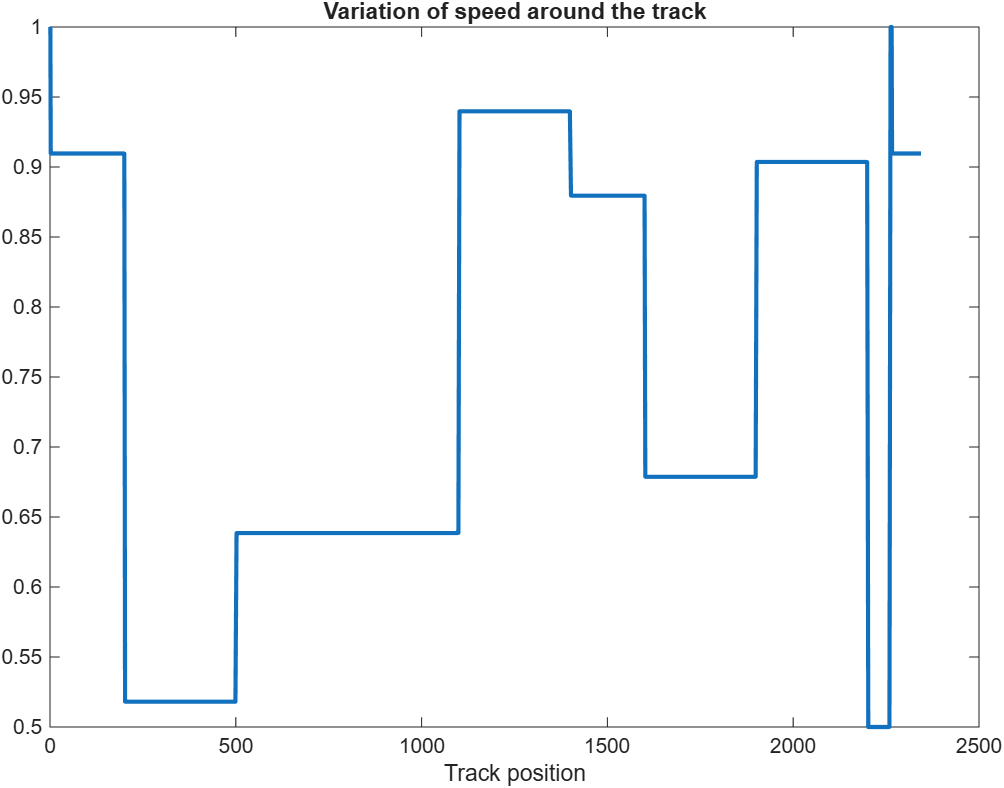

**Figure 4.1** Speed dependence on track position as a ratio

The PI design for speed follows the same principles and implementation as in section 3, that is the throttle is determined from:


$$\mathrm{throttle}=\left(K_{\mathrm{pv}} +\frac{K_{\mathrm{Iv}} }{s}\right)\left(\mathrm{Target}\;\mathrm{speed}-v\right)$$


The PI parameters need to be designed separately, but given the speed dynamics are a first order model, in general the design of suitable parameters is straightforward.

For a car speed model: 


$$M\frac{\mathrm{dv}}{\mathrm{dt}}+B\;v=K\;f$$


a typical but not aggressive choice of parameters would be:


$$K_{\mathrm{pv}} =\frac{B}{K};\;K_{\mathrm{iv}} =\frac{B^2 }{K\;M}$$


This model $M=1500,B=3000,K=150000$ which implies


$$K_{\mathrm{pv}} =0\ldotp 02;\;K_{\mathrm{iv}} =0\ldotp 04$$


**Remark**: As discussed in section 3, code is needed to ensure the throttle demand does not go negative or beyond 100%.

### 4.2 Recovering from a mild spin or skid

If the car is driven too aggressively, it may skid or spin (see Figures in section 5). The app includes a very simple and crude recovery strategy. If it is detected that the car is moving too far from the road centreline, the target speed will automatically be dropped to 10m/s for a set period to allow recovery. Of course this will affect overall performance and may not be sufficient. Where the skid is more severe and the car deviates significantly from the track centreline, this is denoted as a '**crash**' and the simulation is halted.

## 5 The virtual laboratory and student activities

### 5.1 The interface

The virtual laboratory has 3 tabs and its use is largely self explanatory. 

- The main tab as shown in Figure 5.1 has all the sliders where the user makes their choices of control decisions such as PI parameters, target filter pole, throttle (in effect top speed), time limit and constraints.

- The second tab keeps track of the core data from earlier simulations and in particular the performance measures (see section 3.3).

- The 3rd tab provides plots of the steering, target and speed.

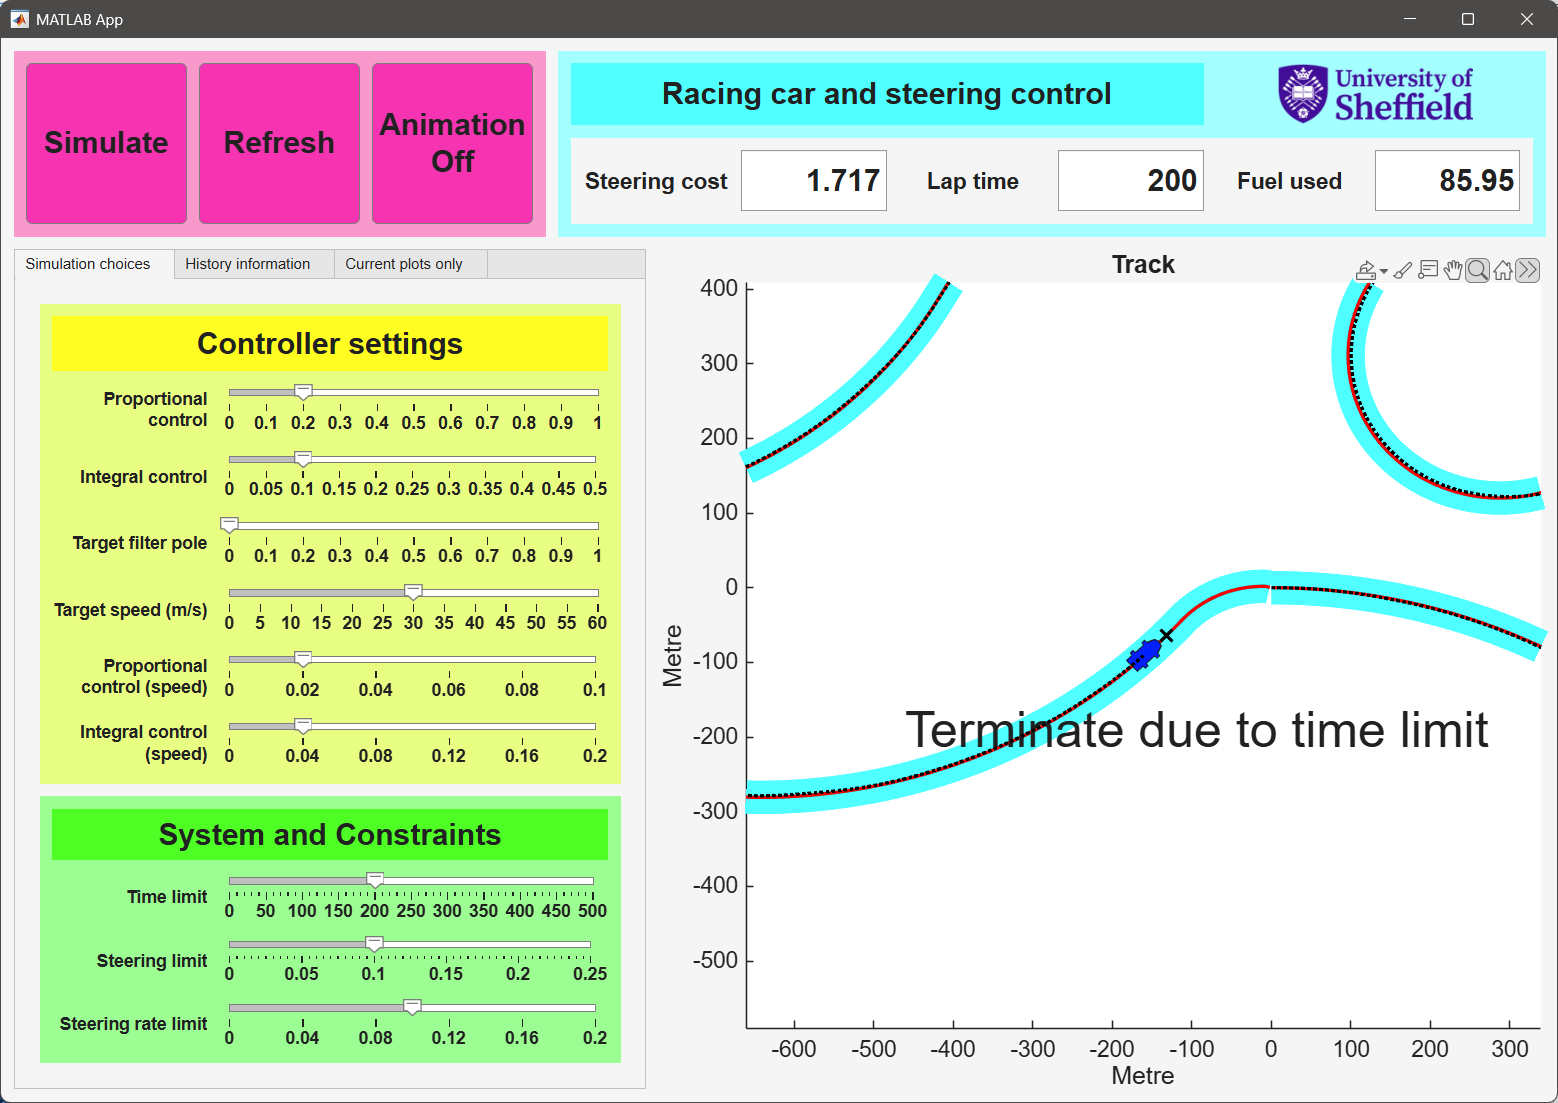

**Figure 5.1** Top tab of the virtual laboratory where design choices are made.

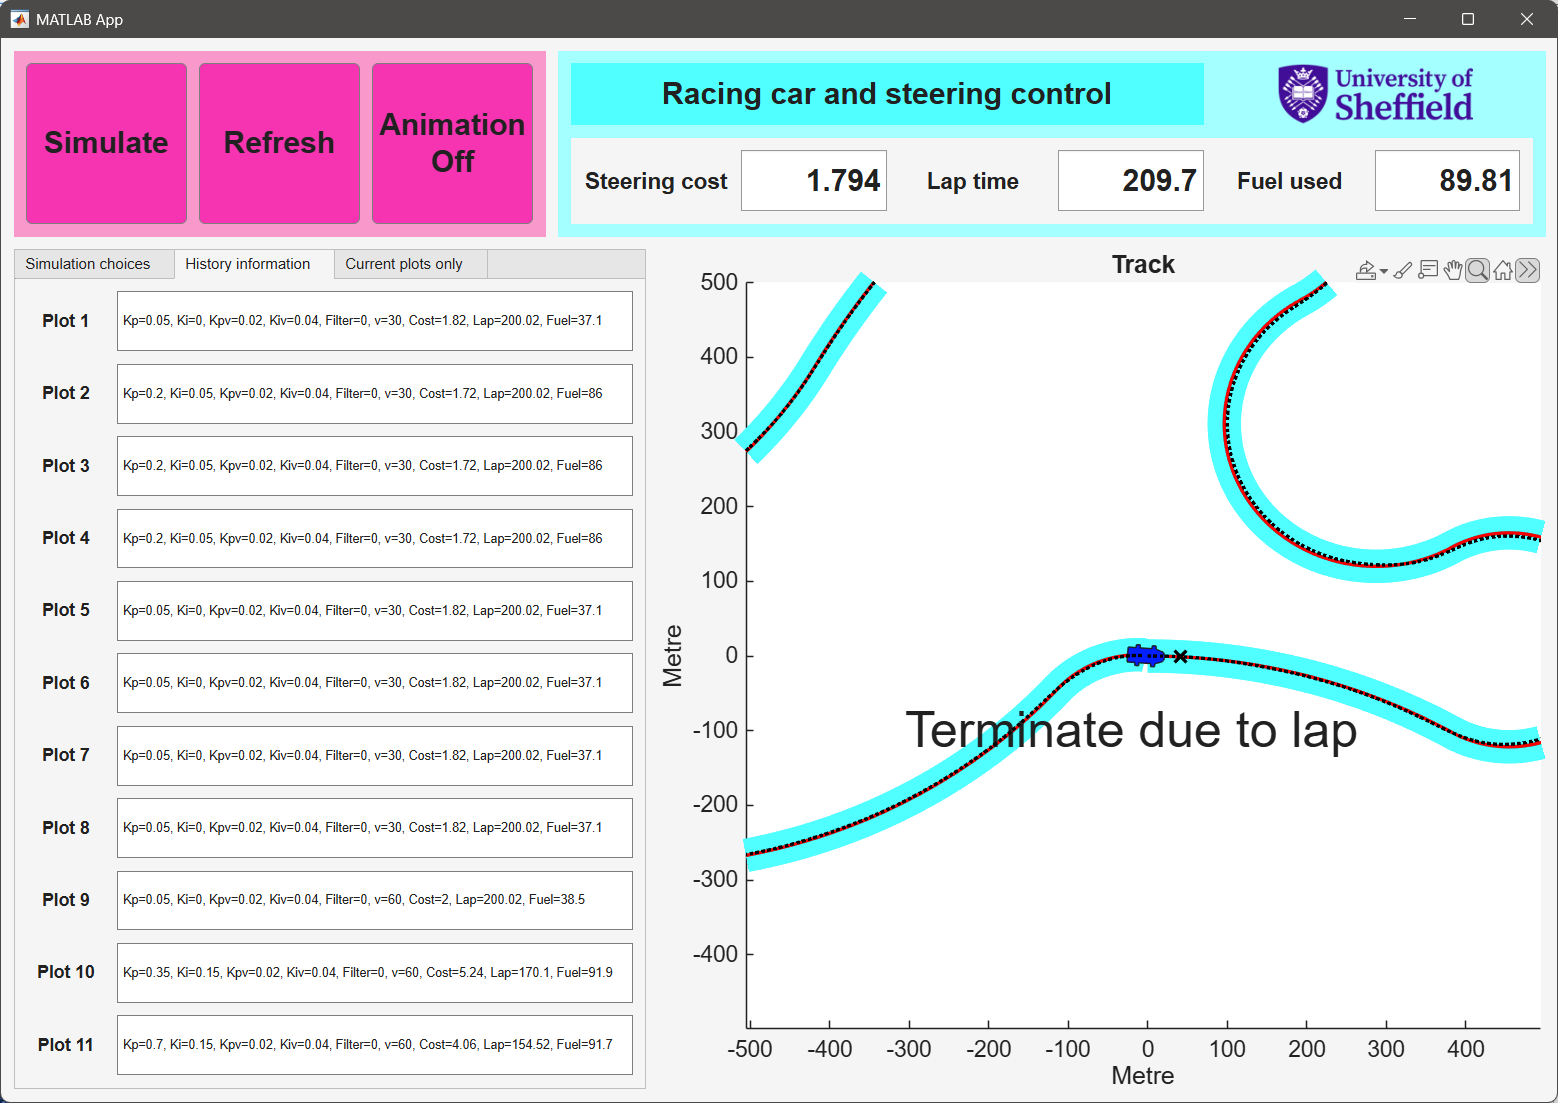

**Figure 5.2**: 2nd tab showing records of previous choices and the associated performances.

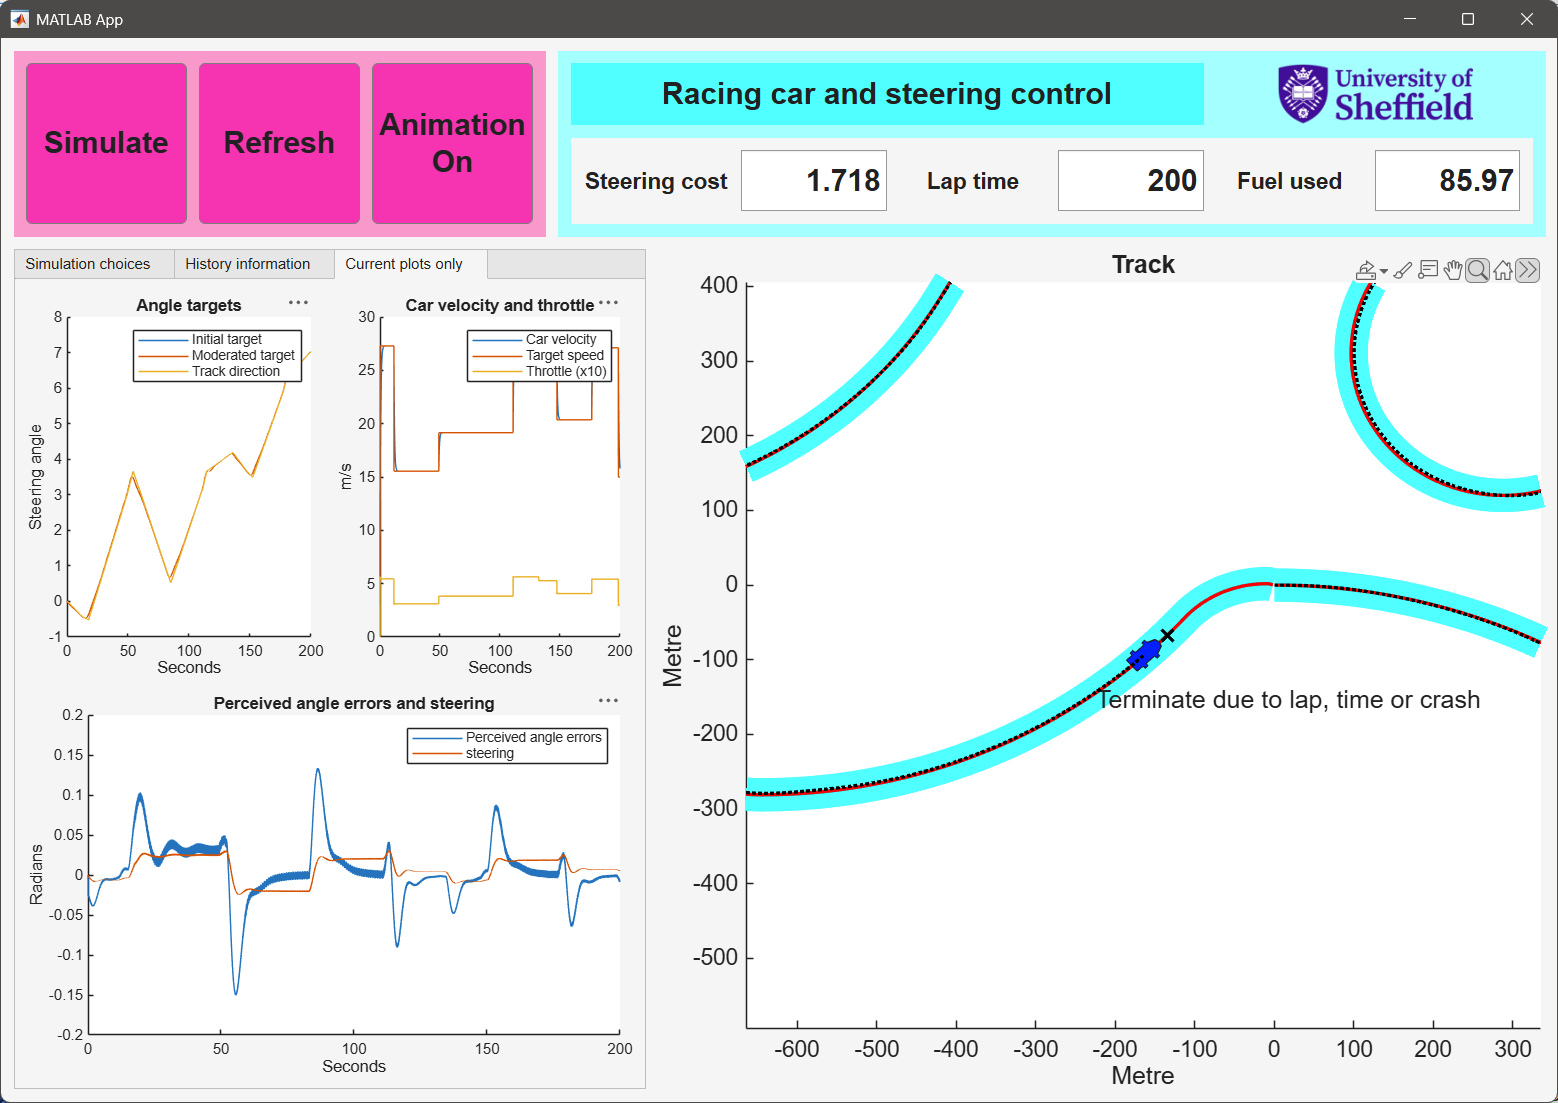

**Figure 5.3** 3rd tab where one can view the steering and throttle signals in detail.

### 5.2 Student activities

The objective is to optimise lap time while minimising fuel and and steering activity. The best solution will vary depending upon other choices such as the constraints on steering.  The following parameters all have an impact on the behaviour. Decide on a scenario and determine the 'optimum' parameters while recognising there there is ultimately a trade off due to there being 3 different performance measures.

- The design of the PI compensator for steering

- The design of the PI compensator for speed control (minor impact).

- The design of the low pass filter for target information.

- The target maximum speed

- The constraints on steering.

- The horizon for the target definition.

**Remark**: The initialisation of the app will have the PI compensator for the steering set at very low values which means the steering is slow to adjust to corners and thus the car keeps leaving the track. Other settings may be too aggressive leading to a crash. See Figure 5.4.

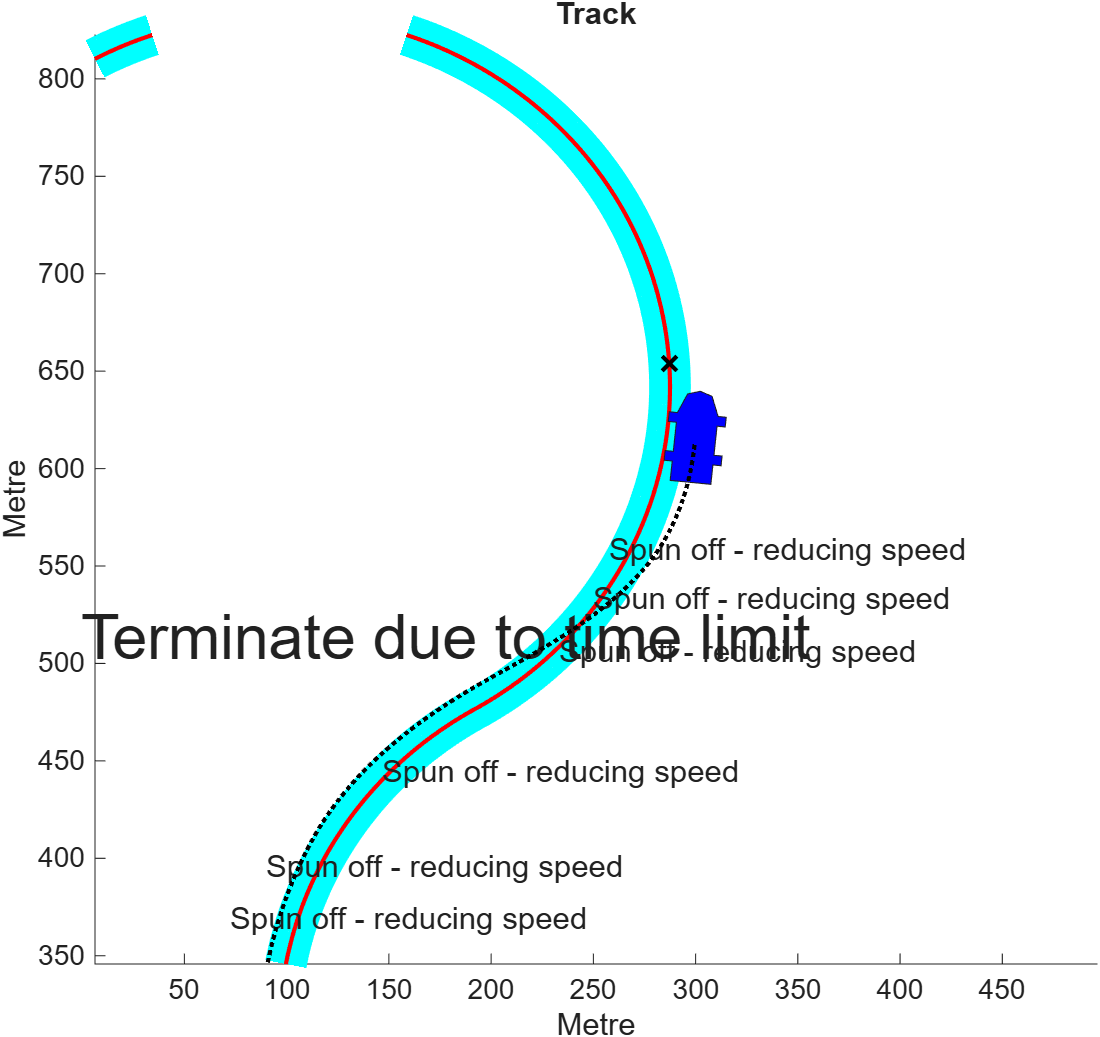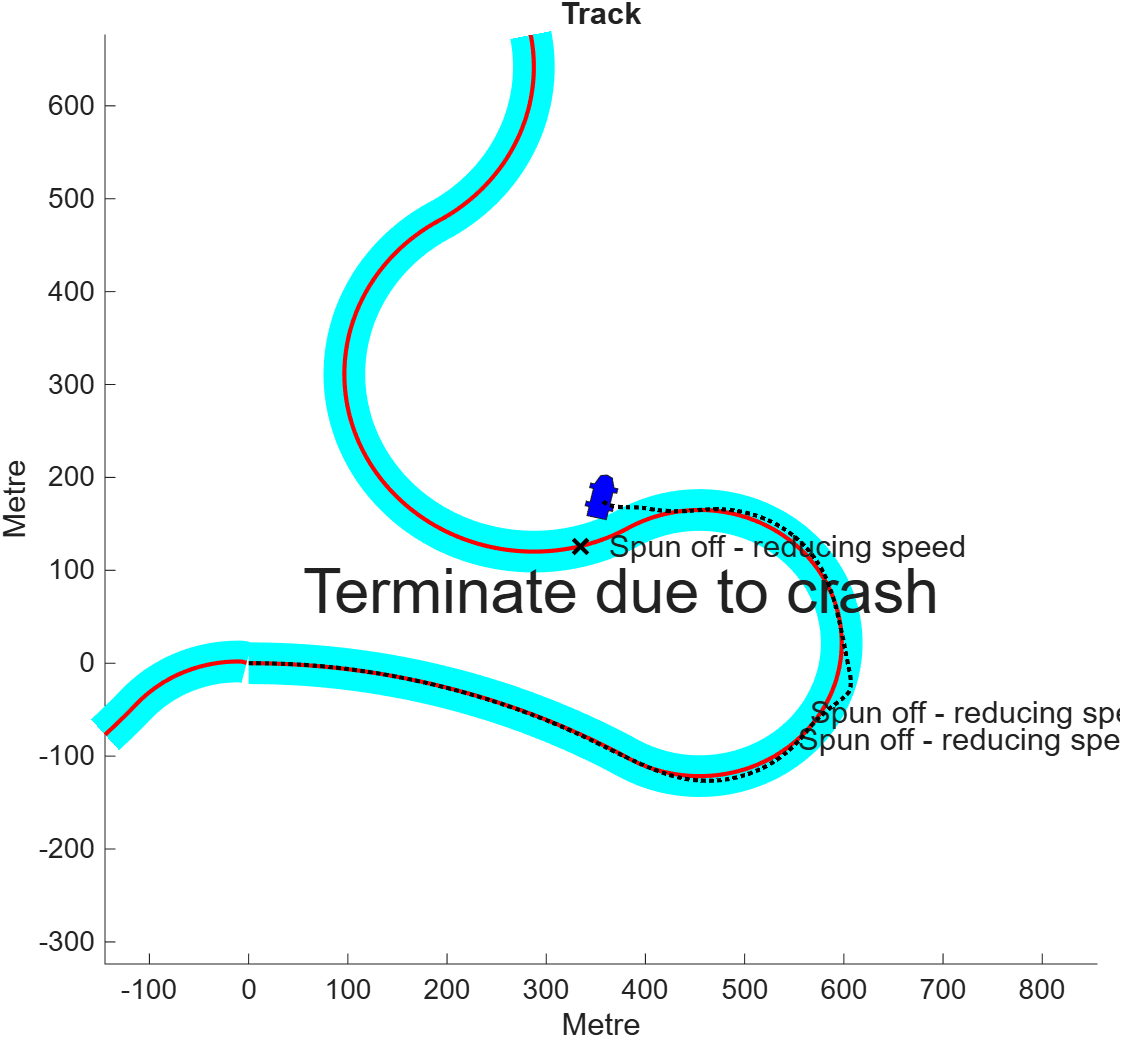

**Figure 5.4** Car repeatedly spinning off with the PI compensator for steering having too low or too high a gain.

## 6 Useful code

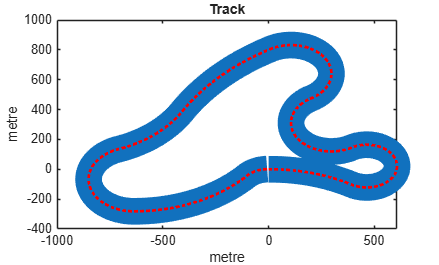

% Model outputs derivatives of the states
% Can use a simple integration for now

function [dx, dy,dvy, dr,  dtheta] = cardynamics(vx, delta,vy, r, theta)
% vx is velcoity
% delta is steering
% vy is an internal state  (must initialise)
% r is an internal state  (must initialise)
% theta is heading angle  (must initialise)


% 1. Vehicle Parameter Definitions
m  = 1500;     % Vehicle mass (kg)

Iz = 2500;     % Yaw moment of inertia (kg*m^2)
lf = 1.2;      % Distance from CG to front axle (m)
lr = 1.6;      % Distance from CG to rear axle (m)
mu = 0.85;     % Road friction coefficient (dry asphalt)
g  = 9.81;     % Gravity acceleration (m/s^2)

% Calculate static vertical tire loads
Fzf = (m * g * lr) / (lf + lr);
Fzr = (m * g * lf) / (lf + lr);

% Cornering stiffness parameters
Cf = 80000;    % Front tire cornering stiffness (N/rad)
Cr = 80000;    % Rear tire cornering stiffness (N/rad)

% 2. Calculate Tire Slip Angles (alpha)
% A small tolerance prevents division by zero if vx is completely stopped
if abs(vx) < 0.1
    vx_eff = 0.1 * sign(vx) + (vx == 0);
else
    vx_eff = vx;
end

alpha_f = delta - atan2((vy + lf * r), vx_eff);
alpha_r = -atan2((vy - lr * r), vx_eff);

% 3. Non-Linear Tire Model (Fiala/Tanh Approximation for Harsh Steering)
% Simulates tire saturation and skidding during sudden changes
Fyf = mu * Fzf * tanh((Cf * alpha_f) / (mu * Fzf));
Fyr = mu * Fzr * tanh((Cr * alpha_r) / (mu * Fzr));

% 4. Equations of Motion (Derivatives of States)
% Lateral Acceleration derivative (dvy/dt)
dvy = ((Fyf * cos(delta) + Fyr) / m) - (vx * r);

% Yaw Acceleration derivative (dr/dt)
dr = (lf * Fyf * cos(delta) - lr * Fyr) / Iz;

% Heading Angle derivative (dtheta/dt)
dtheta = r;

% 5. Global Coordinate Velocity Calculations
dx = vx * cos(theta) - vy * sin(theta);
dy = vx * sin(theta) + vy * cos(theta);

end



% Define track coordinates and curvature and direction and how many points
% used to define the track
% using a 10 m spacing (approx)

function [x,y,theta,direction,numberangles] = definetrack10

% Define track using curvature
theta1 = -ones(1,40)*0.75;  %-35
theta2 = ones(1,60)*4;     % 180
theta3 = -theta2*3/4;          %-180
theta4 = theta2*3/4;           %180
theta5 = ones(1,60)*0.5;     % 20  
theta6 = -ones(1,40)*1;   % -50
theta7 = theta2*2/3;        % 120
theta8=theta2/5;
theta9=-ones(1,12)*4.15;
theta=[0,theta1,theta2,theta3,theta4,theta5,theta6,theta7,theta8,theta9];
theta = theta*pi/180;   % turn into radians
numberangles = length(theta);

% Define the implied direction and x,y coordinates
% Assume a distance of 20m between coordinates
x=0;y=0;d=10;direction=0;
for k=2:length(theta);
    direction(k)=direction(k-1)+theta(k-1);
    x(k)=x(k-1)+d*cos(direction(k));
    y(k)=y(k-1)+d*sin(direction(k));
    if k>numberangles; % Ensure track does not change on the 2nd lap
        x(k)=x(k-numberangles);
        y(k)=y(k-numberangles);
        direction(k)=direction(k-numberangles);
    end
end
%figure(1); clf reset
plot(x,y,'LineWidth',20);hold on
plot(x,y,'r:','LineWidth',2)


% elongate track to ensure continuity
x=[x,x(1:20)];
y=[y,y(1:20)];
theta=[theta,theta(1:20)];
direction=[direction,direction(1:20)];


title('Track')
xlabel('metre')
ylabel('metre')
% end to define track. Has numberangles unique points
end